# 2.27

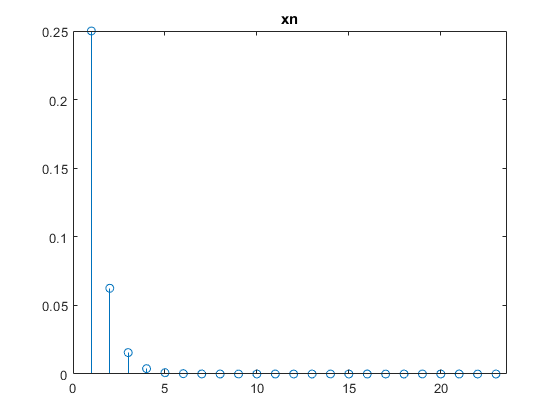

n = 1:100;
un = ones(1,length(n));

an = (1/4) * ones(1,length(n));
an = an.^n;
xn = an.*un;

stem(xn)
title('xn')

xlim([0.0 23.6])
ylim([0.000 0.250])

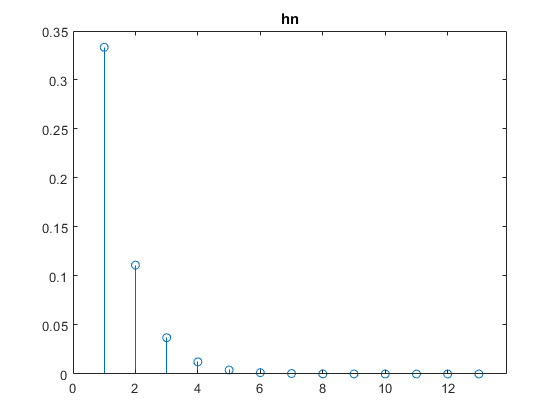


bn = (1/3) * ones(1,length(n));
bn = bn.^n;
hn = bn.*un;

stem(hn)
title('hn')

xlim([0.0 13.9])
ylim([0.000 0.350])

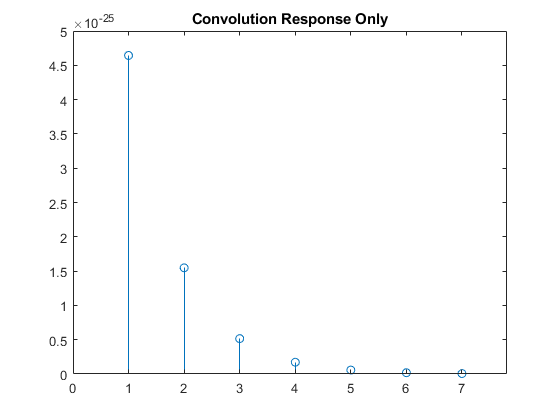


yn = conv(xn,hn,'same');

stem(yn) 
title('Convolution Response Only') 
xlim([0.00 7.81])

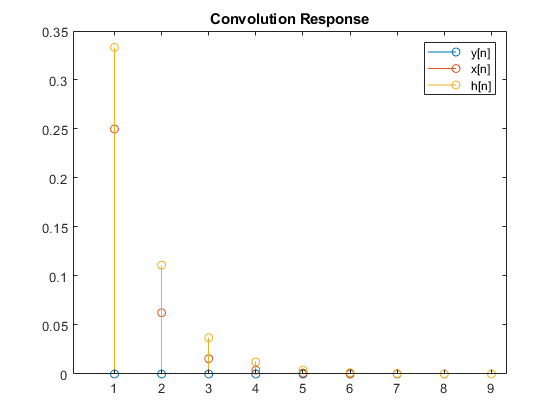

stem(yn)
hold on
stem(xn)
stem(hn)
title('Convolution Response')

legend('y[n]','x[n]','h[n]')
xlim([0.12 9.33])
ylim([0.000 0.350])
hold off